# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 12-Oct-2021 16:15:52

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [3, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Time", "PT4a54", "PT1a04", "PT9a66", "TT1a10", "TT9a56"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Time", "InputFormat", "yyyy/MM/DD HH:mm:ss.SSS");

% Import the data
p1 = readtable("\\cernbox-smb.cern.ch\eos\user\s\slunt\Documents\plant1-25-10.csv", opts)

p1 = 3170×6 table
             Time              PT4a54    PT1a04    PT9a66    TT1a10    TT9a56
    _______________________    ______    ______    ______    ______    ______

    2021/01/15 22:24:44.000    46.278    35.077     44.77    21.428    21.745
    2021/01/15 22:28:37.000    46.275    35.077     44.77    21.428    21.745
    2021/01/15 22:28:38.000    46.275    35.077     44.77    21.428    21.745
    2021/01/15 22:38:37.000    46.275    35.077    44.694    21.428    21.745
    2021/01/15 22:38:38.000    46.275    35.077    44.694    21.428    21.745
    2021/01/15 22:41:05.000    46.275    35.077    44.669    21.428    21.745
    2021/01/15 22:48:37.000    46.275    35.077    44.643    21.428    21.745
    2021/01/15 22:48:38.000    46.275    35.077    44.643    21.428    21.7

## Clear temporary variables

clear opts

Plant 2

opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [3, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Time", "PT4c54", "PT1c04", "PT9c66", "TT1c10", "TT9c56"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Time", "InputFormat", "yyyy/MM/DD HH:mm:ss.SSS");

% Import the data
p2 = readtable("\\cernbox-smb.cern.ch\eos\user\s\slunt\Documents\plant2-25-10.csv", opts)

p2 = 2738×6 table
             Time              PT4c54    PT1c04    PT9c66    TT1c10    TT9c56
    _______________________    ______    ______    ______    ______    ______

    2021/01/15 22:38:37.000    47.027    42.773    46.578    21.193    21.609
    2021/01/15 22:38:38.000    47.027    42.773    46.578    21.193    21.609
    2021/01/15 22:48:37.000    47.027    42.766    46.578    21.193    21.609
    2021/01/15 22:48:38.000    47.027    42.766    46.578    21.193    21.609
    2021/01/15 22:58:38.000    47.027    42.741    46.578    21.193    21.609
    2021/01/15 23:08:37.000    47.027    42.741    46.578    21.193    21.609
    2021/01/15 23:08:38.000    47.027    42.741    46.578    21.193    21.609
    2021/01/15 23:18:37.000    47.027    42.716    46.578    21.193    21.6

Plant 1

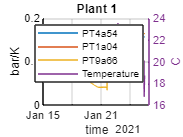

p1acc = p1.PT4a54./(p1.TT1a10+273.15);
p1return = p1.PT9a66./(p1.TT1a10+273.15);
p1liquid = p1.PT1a04./(p1.TT1a10+273.15);

figure
hold on
plot(p1.Time,p1acc)
plot(p1.Time,p1liquid)
plot(p1.Time,p1return)
ylabel('bar/K')

yyaxis right
plot(p1.Time,p1.TT1a10)
ylabel('C')

xlabel('time')

legend('PT4a54','PT1a04', 'PT9a66', 'Temperature')
title('Plant 1')
grid on

Plant 2

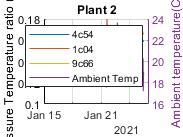

figure
hold on
p2acc = p2.PT4c54./(p2.TT9c56+273.15);
p2return = p2.PT9c66./(p2.TT9c56+273.15);
p2liquid = p2.PT1c04./(p2.TT1c10+273.15);

plot(p2.Time,p2acc)
plot(p2.Time,p2liquid)
plot(p2.Time,p2return)
ylabel('Pressure Temperature ratio (bar/K)')

yyaxis right
plot(p2.Time,p2.TT9c56)
ylabel('Ambient temperature(C)')

legend('4c54','1c04', '9c66', 'Ambient Temp')
title('Plant 2')
grid on

Accumulators

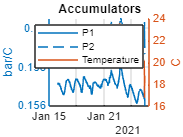

figure
hold on
yyaxis left
plot(p1.Time,p1acc)
plot(p2.Time,p2acc)
ylabel('bar/C')

yyaxis right
plot(p1.Time,p1.TT1a10)
ylabel('C')

legend('P1','P2', 'Temperature')
title('Accumulators')
grid on